### Question 1

Implement the bisection method (textbook §2.1). Your function should have the following signature,

function r = bisection(f, a, b, tol, maxits)

f = @(x) sin(x);
a = 3;
b = 4;
tol = 1e-5;
maxits = 50;
fprintf('%.5f\n',bisection(f, a, b, tol, maxits, 'none'))

3.14159


fprintf('%.5f\n',bisectionrecursive(f, a, b, tol, maxits))

3.14159


a) tol 1e-5 and maxits 16 functions to get us accuracy to 5th decimal place.

b)  replacing sinx with tanx causes a weird solution because there is a discontinuity between 1 and 2 and the bisection function does not know this.

c) done, named bisectionrecursive.

### Question 2

fzero(@sin, [3 4])

ans =    3.141592653589793


fzero(@tan, [1 2], optimset('Display','iter'))

 
 Func-count    x          f(x)             Procedure
    2               1       1.55741        initial
    3               2      -2.18504        interpolation
    4         1.85165      -3.46644        interpolation
    5         1.41615        6.4146        bisection
    6         1.47895       10.8572        interpolation
    7          1.6339      -15.8261        bisection
    8         1.61954      -20.4982        interpolation
    9         1.58798      -58.1765        bisection
   10         1.55642       69.5775        bisection
   11         1.55783       77.1347        interpolation
   12         1.56502       173.074        bisection
   13         1.56861       457.679        bisection
   14          1.5722      -710.251        bisection
   15         1.57182       -980.91        interpolation
   16         1.57041       2574.06        bisection
   17         1.57111      -3169.73        interpolation
   18         1.57104      -4124.11        interpolation
   19         

ans =    1.570796326794897


fzero(@sin, [3 4], optimset('PlotFcns',@optimplotfval));
fprintf('%.5f\n',bisection(f, a, b, tol, maxits, 'iter'))

Iteration: 1 Value: 3.50000
Iteration: 2 Value: 3.25000
Iteration: 3 Value: 3.12500
Iteration: 4 Value: 3.18750
Iteration: 5 Value: 3.15625
Iteration: 6 Value: 3.14062
Iteration: 7 Value: 3.14844
Iteration: 8 Value: 3.14453
Iteration: 9 Value: 3.14258
Iteration: 10 Value: 3.14160
Iteration: 11 Value: 3.14111
Iteration: 12 Value: 3.14136
Iteration: 13 Value: 3.14148
Iteration: 14 Value: 3.14154
Iteration: 15 Value: 3.14157
Iteration: 16 Value: 3.14159
Iteration: 17 Value: 3.14159
3.14159


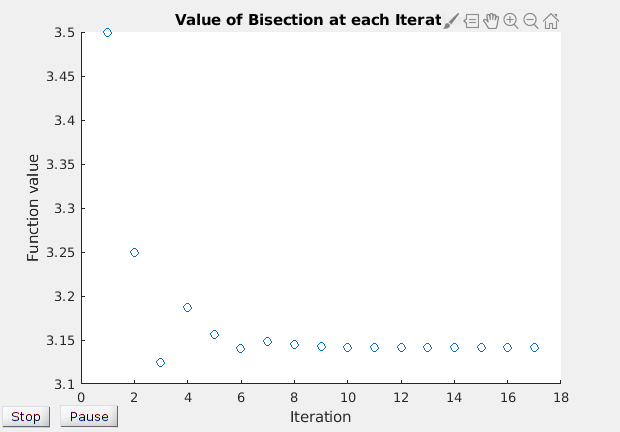

3.14159


fprintf('%.5f\n',bisection(f, a, b, tol, maxits, 'plot'))

a) Up to 5 digits are correct.

b) Done

c) Done

d) Done

function r = bisection(f, a, b, tol, maxits, mode)
    x = 0;
    y = 0;
    format long
    for i = 1:maxits
        r = ( a + b ) / 2;
        if (mode == 'iter')
            fprintf('Iteration: %d Value: %.5f\n', i, r)
        end
        
        x(i) = i;
        y(i) = r;
        
        if (sign(f(r)) == sign(f(a)))
            a = r;
        else
            b = r;
        end
        
        if (abs(a - b)<tol)
            break
        end
        
    end
    
    if (mode == 'plot')
        title('Value of Bisection at each Iteration')
        scatter(x, y)
    end
end

function r = bisectionrecursive(f, a, b, tol, maxits)
    
    r = (a + b) / 2;
    % Base cases
    if (abs(a - b)<tol)
        return
    elseif (maxits == 0)
        return
    end
    
    if (sign(f(r)) == sign(f(a)))
        r = bisectionrecursive(f, r, b, tol, maxits - 1);
    else
        r = bisectionrecursive(f, a, r, tol, maxits - 1);
    end
end